**MATLAB Book: Chapter 4**

% Line plot
% Data: Global temperature in degree celcius (2010-2020)
year=2010:1:2020;
temp=[14.46 14.55 14.48 14.67 14.82 15.16 14.83 ...
       14.88 14.89 15.05 14.78];
plot(year,temp,'b-o','linewidth',1.5); 
xlabel('Years');
ylabel('Temperature (Degree celcius)');
title('Line plot of global temperature (2010-2020)')
grid on;
% Line plot
% Data of global temperature from 2010:2020
year=2010:1:2020;
temp_C=[14.46 14.55 14.48 14.67 14.82 15.16 14.83 ...
       14.88 14.89 15.05 14.78];
temp_F=[58.028 58.19 58.064 58.406 58.676 59.288 ...
       58.694 58.78 58.802 59.09 58.604];
plot(year,temp_C,'b-o','linewidth',1.5); 
hold on;
xlabel('Years');
ylabel('Temperature');
grid on;
plot(year,temp_F,'g-o','linewidth',1.5);
xlabel('Years');
ylabel('Temperature');
title('Line plot of global temperature (2010-2020)')
grid on;
legend('Temperature in degree celcius',...
                'Temperature in farenhite')
% Subplot
% Data of global temperature from 2010:2020
% Temperature unit: degree celcius and farenhite
year=2010:1:2020;
temp_C=[14.46 14.55 14.48 14.67 14.82 15.16 14.83 ...
       14.88 14.89 15.05 14.78];
temp_F=[58.028 58.19 58.064 58.406 58.676 59.288 ...
       58.694 58.78 58.802 59.09 58.604];
subplot (1,2,1);
plot(year,temp_C,'b-o','linewidth',1.5); 
xlabel('Years');
ylabel('Temperature (degree celcius)');
title('Global temperature (2010-2020)')
grid on;
subplot (1,2,2);
plot(year,temp_F,'k-o','linewidth',1.5);
xlabel('Years');
ylabel('Temperature (farenhite)');
title('Global temperature (2010-2020)')
grid on

Bar plot

% Bar plot
% Data: Global CO2 emission (2010-2020)
year=2010:1:2020;
CO2=[30.5824 31.4595 31.806 32.3707 32.3886 32.3655 ...
     32.3747 32.8374 33.5133 36.4568 34.0752];
bar(year,CO2,'b');
ylim([20 40]);
xlabel('Years');
ylabel('CO2 emission (Gt)')
title('Global CO2 Emission (2010-2020)')
grid on

Double-axis Line plot

%% Double-axis plot
% Data: Price of Copper and Steel (2000-2020)
year=2000:5:2020;
copper_price=[1813 3679 7535 5631 5786];
steel_price=[296 633 716 543 491];
colororder({'k','b'})
yyaxis left
plot(year,copper_price,'k-o','linewidth',1.5);
xlim([2000 2020]);
ylim([0 8000]);
xlabel('Year');
ylabel('Copper Price ($/Tonne)');
hold on
yyaxis right
plot(year,steel_price,'b-o','linewidth',1.5);
ylim([200 1000]);
ylabel('Steel Price ($/Tonne)');
legend({'Copper Price','Steel Price'},'Location','Northwest');
title('Price of Copper and Steel (2000-2020)')
grid on
% Pie plot
% Data: Electricity consumption by different sectors in USA (2018)
% x: Percentage of Consumption in four different sectors in USA 
x = [35.4,25.9,2,38.5];
subplot(1,2,1);
pie(x);
title('Without explode feature')
subplot(1,2,2);
explode=[1,1,1,1];
pie(x,explode);
title('With explode feature')
labels = {'Commercial','Industrial','Transportation','Residential'};
legend(labels,'Location','best')
hold off;
% Heatmap
% Data: Electricity day-ahead market price (2019)
% LMP: Local Marginal Price ($/MW)
% Date: Jan-01-2019 to Jan-07-2019
% Time: 10 AM to 03 PM
clc; clear;
LMP = [38.8 38.5 39.6 42.8 42.8 40.8;...
       42.2 42.4 43.4 45.0 58.0 55.3;...
       40.4 39.6 41.4 44.0 56.9 50.9;...
       38.8 39.5 40.0 43.6 55.3 48.5;...
       36.6 36.5 36.5 38.2 39.4 39.6;...
       32.7 33.1 34.5 35.0 36.5 34.9;...
       32.3 33.5 35.1 39.4 48.2 56.0];
Time = {'10 AM','11 AM','12 PM','01 PM','02 PM','03 PM'};
Date = {'Jan-01','Jan-02','Jan-03','Jan-04','Jan-05','Jan-06','Jan-07'};
H = heatmap(Time,Date,LMP);
H.Title = 'Electricity day-ahead market price ($/MW)';
H.XLabel = 'Time';
H.YLabel = 'Date'

H =   HeatmapChart (Electricity day-ahead market price ($/MW)) with properties:

        XData: {6×1 cell}
        YData: {7×1 cell}
    ColorData: [7×6 double]

  Show all properties


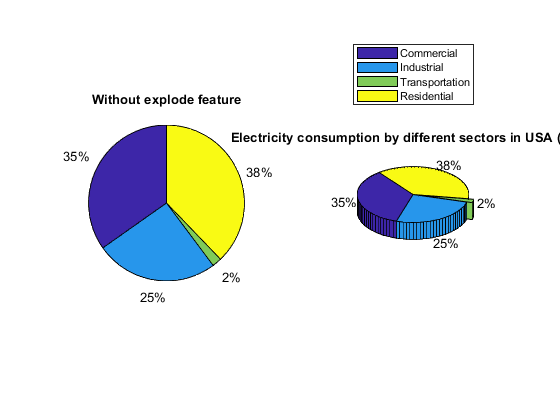

%% 3D pie plot
% Data: Electricity consumption by different sectors in USA (2018)
clc;clear;
x = [35.4,25.9,2,38.5];
explode=[0,0,1,0];
pie3(x,explode);
title('Electricity consumption by different sectors in USA (2018)')
labels = {'Commercial','Industrial','Transportation','Residential'};
legend(labels,'Location','best')

% Area plot 
% Data: Typical load curve over 24 hours in MW 
clc; clear;
a=xlsread('Area_plot_2.xlsx');
y=a(:,2:4)
area(y);
xlim([0 24]);
xlabel('Hours');
ylabel('Load (MW)');
title('Load curve in MW')
legend('Base load','Shoulder load','Peak load','Location','northwest');